#### ADVANCED DIGITAL SIGNAL PROCESSING

NAME: **GIDEON OPOKU | **STUDENT ID:** 20735677 |** INDEX NUMBER:** PG3044620 |**

**LAB EXERCISE ONE**

**a.**

% Frequency of the sinusoids
f = 4000;
% Period of the sinusoids
T = 1/f;
% Generation of 25 samples per period of the sine wave
tt = -T:1/(25*f):T;

**b.**

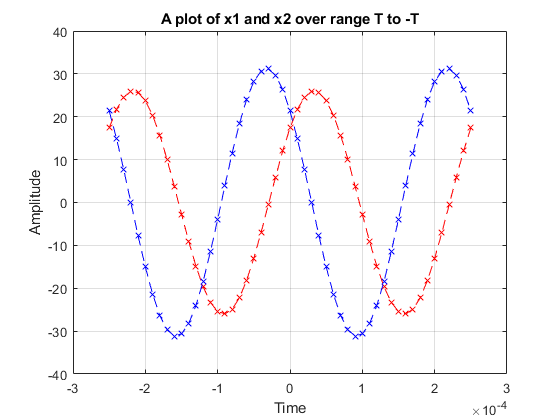

% D is the day
D = 10;
% M is the month
M = 9;
% A1 is the age
A1 = 26; 

% Given that;
A2 = 1.2*A1; 

tm1 = (37.2/M)*T; 
tm2 = -(41.3/D)*T;

x1 =  A1*cos(2*pi*f*(tt-tm1));
x2 =  A2*cos(2*pi*f*(tt-tm2));

plot(tt,x1,'--rx');
grid on; 
hold on;
plot(tt,x2,'--bx');
title('A plot of x1 and x2 over range T to -T');
ylabel('Amplitude');
xlabel('Time');

**c.**

% Creating a sum of the third sinusoid
x3 = x1 + x2;

**d.**

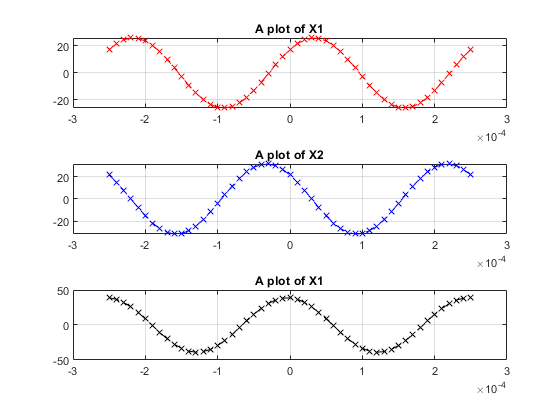

%Printing the three plots
subplot(3,1,1); 
plot(tt,x1,'--rx'); 
grid on;
title('A plot of X1');

subplot(3,1,2); 
plot(tt,x2,'--bx'); 
grid on;
title('A plot of X2');

subplot(3,1,3); 
plot(tt,x3,'--kx');
grid on;title('A plot of X1');

**3.1** Therotical Calculations

**a. **

% The "time-location of positive peak" and amplitude are read on the graph as; 

    A1 = 25.9088; tm1 = 3e-05

% The phase is calculated by  phase = -2*pi*f*t

    Therefore;    phase = -2*pi*f*tm1 = -0.75398 rad

% The "time-location of positive peak" and amplitude are read on the graphg as; 

    A2 = 31.1384; tm2 = -3e-05

% The phase is calculated by  phase = -2*pi*f*t

     phase = -2*pi*f*tm2 =  0.75398 rad

**b.** 

% The "time-location of positive peak" and amplitude are read on the graph as; 

    A3 = 38.7553; tm3 = 0.00025

% The phase is calculated by  phase = -2*pi*f*t

    Therefore;  phase =-6.2834 rad

**c.** 

x1 = 25.9088*exp(-0.75398i);

18.8867 -17.7358i   

ans = 18.8867 - 17.7358i

x2 = 31.1384*exp(0.75398i);

22.6990 +21.3157i

ans = 22.6990 + 21.3157i

x3 = x1+ x2

41.5857 + 3.5799i

ans = 41.5857 + 3.5799i

41.7395*exp(0.0859i)

ans = 41.5856 + 3.5810i

**3.2** Complex Amplitude

% Generating x1 with complex amplitude representation
z = real(A1*exp(1i*(2*pi*4000)*tt));